Let's start by fixing the path

clear
clc

full_path='D:\MATLAB AP Package Beta\';
project_path='D:\MATLAB AP Package Beta\Scratch\Week 5\';

addpath(genpath([full_path,'Data\']));
addpath(genpath([full_path,'Functions\']));
addpath(genpath(project_path));
cd(project_path);

clear full_path project_path  


## Bernanke and Kuttner (2005):

clear
clc

load ddates
load dff

% Download Kuttner surprises
fileName = 'kuttnerSurprises.xlsx';
fileID = '1Up04KzMYug9zyKWYFdrOgQD7S6n_Q7d7';
filePath = [pwd,'\Data'];
getGoogleDriveData(fileName, fileID, filePath);

% Read them in
opts = detectImportOptions(fileName);
data = readtable(fileName, opts);
data.Properties.VariableNames{'Var1'} = 'date';

% Assign to vector
data.dates = 10000 * year(data.date) + ...
               100 * month(data.date) + ...
                     day(data.date);

[~, ia, ib] = intersect(ddates, data.dates);

fomcMeetings = zeros(size(ddates));
fomcMeetings(ia) = 1;
fomcMeetings(ddates<data.dates(1)) = nan;
fomcMeetings(ddates>data.dates(end)) = nan;

fomcSurprises = nan(size(ddates));
fomcSurprises(ia) = data.Surprise(ib);

prt(nanols(dmkt, [ones(size(dmkt)) fomcMeetings]));

prt(nanols(10000*dmkt,[ones(size(dmkt)) fomcSurprises]));
e = find(ddates>20030000);
prt(nanols(10000*dmkt(1:e), [ones(size(dmkt(1:e))) fomcSurprises(1:e)]));


## Some classic FOMC results. Start with Savor and Wilson (2013, 2014):

First we need to get the scheduled macroeconomic announecments from Savor and Wilson (2013, 2014). Their dates choice is a bit weird, but it doesn't really matter for the results:

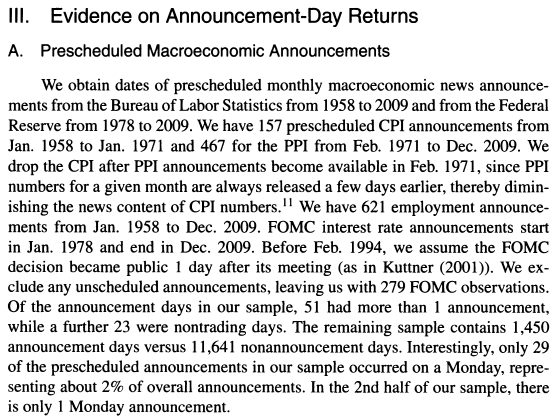

They don't really say exactly how they collected their data, but we'll try to get as close as possible. First, we'll start with the BLS data. 

FRED allows you to download release dates through their API (read more at [https://fred.stlouisfed.org/docs/api/fred/).](https://fred.stlouisfed.org/docs/api/fred/).) For that, you'll need an account with them and API key. I've stored mine here, which you could use temporarily, but you should really get your own if you plan on doing this often.

clear
clc

apiKey = '625723b3573b7c847f626c6df4254c03';

We'll start the pull by first getting a list of all their releases. We need to do this to figure out the release id's, which FRED requires for the actual pull of the dates.

First we need to specify the request we'll send to the API. It's like downloading any file from a URL using the webread() command. The file_type=json ensures that the data is stored in a structure.

fredApiRequest = ['https://api.stlouisfed.org/fred/releases?api_key=', apiKey, ...
                                                          '&file_type=json'];

releaseData = webread(fredApiRequest);

releaseData.releases is an array of structures, where each of those structure has information on a particular release. We'll convert this to a cell and extract the names:

releasesCell = [releaseData.releases];
releaseNames = cellfun(@(x) x.name, releasesCell, 'UniformOutput', 0);

Now we need to identify the names of the releases we need and store their release id's:

ppiRow = find(strcmp(releaseNames, 'Producer Price Index'));
ppiReleaseID = releasesCell{ppiRow}.id;

cpiRow = find(strcmp(releaseNames, 'Consumer Price Index'));
cpiReleaseID = releasesCell{cpiRow}.id;

unempRow = find(strcmp(releaseNames, 'Employment Situation'));
unempReleaseID = releasesCell{unempRow}.id;

% Get the PPI dates
apiRequest = ['https://api.stlouisfed.org/fred/release/dates?api_key=',apiKey, ...
                                                            '&file_type=json', ...
                                                            '&release_id=',char(num2str(ppiReleaseID))];
ppiData = webread(apiRequest);
ppiDates = struct2cell(ppiData.release_dates)';
ppiDates = datetime(ppiDates(:,2));
ppiDates = 10000 * year(ppiDates) + ...
             100 * month(ppiDates) + ...
                   day(ppiDates);

% Get the CPI dates
apiRequest = ['https://api.stlouisfed.org/fred/release/dates?api_key=',apiKey, ...
                                                            '&file_type=json', ...
                                                            '&release_id=',char(num2str(cpiReleaseID))];
cpiData = webread(apiRequest);
cpiDates = struct2cell(cpiData.release_dates)';
cpiDates = datetime(cpiDates(:,2));
cpiDates = 10000 * year(cpiDates) + ...
             100 * month(cpiDates) + ...
                   day(cpiDates);

% Get the Unemployment dates
apiRequest = ['https://api.stlouisfed.org/fred/release/dates?api_key=',apiKey, ...
                                                            '&file_type=json', ...
                                                            '&release_id=',char(num2str(unempReleaseID))];
unempData = webread(apiRequest);
unempDates = struct2cell(unempData.release_dates)';
unempDates = datetime(unempDates(:,2));
unempDates = 10000 * year(unempDates) + ...
               100 * month(unempDates) + ...
                     day(unempDates);

% Get the FOMC dates manually
fomcDates = getFOMCDates();

Error using webread (line 122)
Web service operation terminated by user while accessing URL 'https://www.federalreserve.gov/monetarypolicy/fomchistorical1949.htm?options=text'.

Error in getFOMCDates (line 68)
    thisYearData = webread(fomcURL,'options','text');

fomcDates(fomcDates<datetime(1993,12,31)) = fomcDates(fomcDates<datetime(1993,12,31)) + days(1);

fomcDates = 10000 * year(fomcDates) + ...
              100 * month(fomcDates) + ...
                    day(fomcDates);

Now let's create indicator vectors for these announcements of the size that corresponds to our daily dates:

load ddates

% Initiate those
cpiDate = zeros(size(ddates));
ppiDate = zeros(size(ddates));
unempDate = zeros(size(ddates));
fomcDate = zeros(size(ddates));

% Intersect & assign
[~, ia, ~] = intersect(ddates, cpiDates);
cpiDate(ia) = 1;
[~, ia, ~] = intersect(ddates, ppiDates);
ppiDate(ia) = 1;
[~, ia, ~] = intersect(ddates, unempDates);
unempDate(ia) = 1;
[~, ia, ~] = intersect(ddates, fomcDates);
fomcDate(ia) = 1;

% Save these
save Data/macro_announcements cpiDate ppiDate unempDate fomcDate

Now let's replicate:

clear
clc

load dff
load ddates
load macro_announcements

r = find(ddates>19710000, 1, 'first');

% Create the inflation announcement
inflDate = zeros(size(ddates));
inflDate(1:r-1) = cpiDate(1:r-1);
inflDate(r:end) = ppiDate(r:end);

macroDate = 1*(inflDate + unempDate + fomcDate >0);

s = find(ddates>19580000, 1, 'first');
e = find(ddates>20100000,1 , 'first');

const = ones(size(dmkt));

dmkt = 1e4 * dmkt;
y = dmkt(s:e);
x = [const(s:e) macroDate(s:e)];
res1 = nanols(y, x);
prt(res1)

x = [const(s:e) macroDate(s:e) dmkt(s-1:e-1) dmkt(s-1:e-1).*dmkt(s-1:e-1)];
res2 = nanols(y, x);
prt(res2)

wkDay = weekday(datetime(ddates,'ConvertFrom','yyyyMMdd'));
mondInd = 1 * (wkDay == 2);
tuesInd = 1 * (wkDay == 3);
wedInd = 1 * (wkDay == 4);
thurInd = 1 * (wkDay == 5);

x = [const(s:e) macroDate(s:e) dmkt(s-1:e-1) dmkt(s-1:e-1).*dmkt(s-1:e-1) ...
     mondInd(s:e) tuesInd(s:e) wedInd(s:e) thurInd(s:e)];
res3 = nanols(y, x);
prt(res3)

   
res = [res1.beta(1)  res2.beta(1)  res3.beta(1); 
       res1.tstat(1) res2.tstat(1) res3.tstat(1);
       res1.beta(2)  res2.beta(2)  res3.beta(2);
       res1.tstat(2) res2.tstat(2) res3.tstat(2);
       nan           res2.beta(3)  res3.beta(3);
       nan           res2.tstat(3) res3.tstat(3);
       nan           res2.beta(4)  res3.beta(4);
       nan           res2.tstat(4) res3.tstat(4);
       nan           nan           res3.beta(5);
       nan           nan           res3.tstat(5);
       nan           nan           res3.beta(6);
       nan           nan           res3.tstat(6);
       nan           nan           res3.beta(7);
       nan           nan           res3.tstat(7);
       nan           nan           res3.beta(8);
       nan           nan           res3.tstat(8);
       res1.nobs     res2.nobs     res3.nobs;
       res1.rbar     res2.rbar     res3.rbar];

info.rnames = char('','Intercept', 't_Intercept','Ann. day','t_Ann. day','MKTRF_t-1','t_MKTRF_t-1','(MKT_t-1)^2','t_(MKT_t-1)^2',...
                    'Monday','t_Monday','Tuesday','t_Tuesday','Wednesday','t_Wednesday','Thursday','t_Thursday','N','Adj. R^2');
mprint(res,info);

prt(nanols(dmkt(s:end),[ones(size(dmkt(s:end))) macroDate(s:end)]))


Compare with:

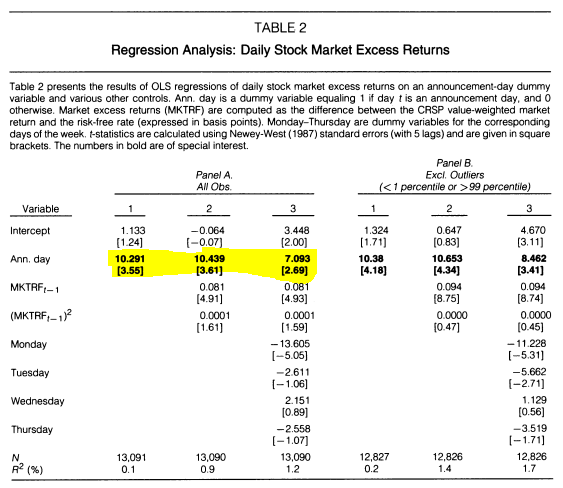

## Let's do Savor and Wilson (2014) next:

Start with calculating the daily betas.

clear
clc

load dret
load ddates
load dff

nDays = size(dret, 1);
nStocks = size(dret, 2);

rptdRf = repmat(drf, 1, nStocks); 
xret = dret - rptdRf;

s = find(ddates > 19550000);
s = 253;

% Convert ddates to datetime:
ddates = datetime(ddates, 'ConvertFrom', 'yyyyMMdd');

dBeta = nan(size(dret));

for i = s:nDays
    ddates(i)
    % Find the stocks with sufficient data (horizontal index):
    b = max(find(ddates > (ddates(i) - years(1)), 1, 'first'), 2);
    indPastYr = [b:i]'; 
    tempRet = xret(indPastYr, :);
    hor_ind = find( sum(isfinite(tempRet), 1) > 120 & ...
                    isfinite(tempRet(end, :)));
    nStocksToLoop = length(hor_ind);
    
    const = ones(size(indPastYr));
    
    for k = 1:nStocksToLoop
        j = hor_ind(k);
        res = nanols(xret(indPastYr, j), [const dmkt(indPastYr) dmkt(indPastYr-1)]);
        dBeta(i, j) = res.beta(2) + res.beta(3); % Dimson beta
    end
    
end

save Data/dBeta dBeta -v7.3

Now that we have the daily betas, let's replicate their main figure:

clear
clc

load dBeta
load dret
load dme
load ddates
load macro_announcements

r = find(ddates>19710000, 1, 'first');

% Create the inflation announcement
inflDate = zeros(size(ddates));
inflDate(1:r-1) = cpiDate(1:r-1);
inflDate(r:end) = ppiDate(r:end);

macroDate = 1*(inflDate + unempDate + fomcDate >0);

s = find(ddates>19640000, 1, 'first') - 1;
e = find(ddates<20120000, 1, 'last');

ind = makeUnivSortInd(dBeta, 10);
dres = runUnivSort(dret, ind, ddates, dme, 'timePeriod', ddates([s e])', ...
                                           'factorModel', 1, ...
                                           'addLongShort', 0, ...
                                           'printResults', 0, ...
                                           'plotFigure', 0);

indMacro = macroDate(s+1:e) == 1;
ptfRets = dres.pret(2:end, :);
ptfBetas = dres.factorLoadings.b;

avgRetMacroDays = mean(ptfRets(indMacro, :));
avgRetNonMacroDays = mean(ptfRets(~indMacro, :));

x = ptfBetas;

figure;

% Plot the announcement days
y = 1e4*avgRetMacroDays;
scatter(x, y, 'd', 'filled', 'MarkerFaceColor', 'k');
hold on;
Fit = polyfit(x,y,1); % x = x data, y = y data, 1 = order of the polynomial i.e a straight line 
plot(x, polyval(Fit,x), 'k')

% Plot the non-announcement days
y = 1e4*avgRetNonMacroDays;
scatter(x, y, 's', 'filled', 'MarkerFaceColor', 'k');
Fit = polyfit(x,y,1); % x = x data, y = y data, 1 = order of the polynomial i.e a straight line 
plot(x, polyval(Fit,x), '--k')


xlabel('Capital asset pricing model beta');
ylabel('Average excess return (bps)');
legend('a-day','','n-day', 'Location', 'Northwest');

Compare with:

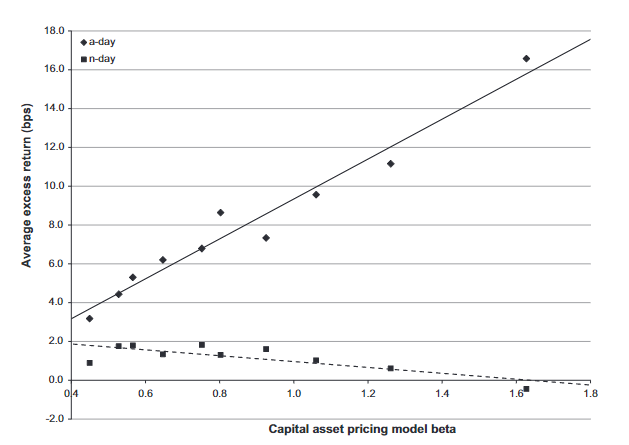

## Lucca and Moench (2015):

Let's start by pulling by minute-by-minute prices for SPY from TAQ. Their data actually comes from Thomson Reuters TickHistory, but we'll see that this works quite well too.

clear
clc

load ddates

% Initialize your parameters
Params.username = usernameUI();                                            % Input your WRDS username
Params.pass     = passwordUI();                                            % Input your WRDS password

% Call the WRDS connection
WRDS = callWRDSConnection(Params.username,Params.pass);

mktOpenDur = [datetime(2000,1,1,9,30,0):minutes:datetime(2000,1,1,16,0,0)]';
[hmMktOpenDur(:,1),  hmMktOpenDur(:,2)] = hms(mktOpenDur);
hmMktOpenDur = 100*hmMktOpenDur(:,1) + hmMktOpenDur(:,2);

nDays = length(ddates);
nMinutes = size(hmMktOpenDur, 1);

spyPrices = nan(nDays, nMinutes);

startDate = find(ddates>19940000, 1, 'first');
ticker = 'SPY';

for i = startDate:nDays
    if floor(i/252) > floor((i-1)/252)
        ddates(i)
    end    
    
    yrChr = floor(ddates(i)/10000);

    qry = ['select date, time_m, price from TAQM_', char(num2str(yrChr)), '.WCT_', ...
            char(num2str(ddates(i))),' where sym_root=''', ticker, ''''];
    try
        prcTable = fetch(WRDS, qry);
    catch 
        prcTable = table;
    end
    
    if height(prcTable)>0
        
        prcTable.date = datetime(strcat(prcTable.date,repmat({' '}, height(prcTable), 1), prcTable.time_m));

        [prcTableHM(:,1),  prcTableHM(:,2)] = hms(prcTable.date);
        prcTable.prcTableHM = 100*prcTableHM(:,1) + prcTableHM(:,2);


        
        lastPricePerMinute = varfun(@(x) x(end,:), prcTable, 'GroupingVariables', {'prcTableHM'}, ...
                                                             'InputVariables', {'price','prcTableHM'});        
        [~, ia, ib] = intersect(hmMktOpenDur, lastPricePerMinute.prcTableHM);
        spyPrices(i, ia) = lastPricePerMinute.Fun_price(ib)';
        clear prcTableHM
    end

end

save Data/spyPrices spyPrices -v7.3

Now let's replicate:

clear
clc

load ddates
load spyPrices

s = find(ddates > 20090000, 1, 'first');
spyPrices(s:end, :) = nan;
spyRets = [spyPrices'./lag(spyPrices',1,nan)-1]';
mktOpenDur = [datetime(2000,1,1,9,30,0):minutes:datetime(2000,1,1,16,0,0)]';

load macro_announcements

indFOMC = find(fomcDate == 1);
indNotFOMC = find(fomcDate == 0);
indNotFOMC([1 end]) = [];

figure;
subplot(1, 3, 1)
temp=[nanmean(spyRets(indFOMC-1,:), 1) ; ... 
     nanmean(spyRets(indNotFOMC-1,:), 1)]';
temp(isnan(temp)) = 0;
cumTemp = 100 * (cumprod(1+temp) - 1);
plot(mktOpenDur, cumTemp);
ylabel('Percent');
ylim([-0.2 1])

subplot(1, 3, 2)
temp=[nanmean(spyRets(indFOMC,:), 1); ... 
      nanmean(spyRets(indNotFOMC,:), 1)]';
temp(1,: ) = (cumTemp(end,:)/100);
cumTemp = 100 * (cumprod(1+temp) - 1);
plot(mktOpenDur, cumTemp);
ylim([-0.2 1])
hold on;
fomcStatement = datetime(2000,1,1,14,15,0);
line([fomcStatement fomcStatement],[-0.2 1],'Color',[0.8 0.8 0.8])

subplot(1, 3, 3)
temp=[nanmean(spyRets(indFOMC+1,:), 1); ... 
     nanmean(spyRets(indNotFOMC+1,:), 1) ]';
temp(1,: ) = (cumTemp(end,:)/100);
cumTemp = 100 * (cumprod(1+temp) - 1);
plot(mktOpenDur, cumTemp);
ylim([-0.2 1])

Compare with: